hold on
grid on
x = [
12
12
12
10
10
8
8
6
6
4
4
2
2]

x =     12
    12
    12
    10
    10
     8
     8
     6
     6
     4


y = [
3.11
3.147
3.125
2.604
2.628
2.044
2.119
1.407
1.417
0.941
0.935
0.675
0.682
]

y =     3.1100
    3.1470
    3.1250
    2.6040
    2.6280
    2.0440
    2.1190
    1.4070
    1.4170
    0.9410


xlim([0;12])
ylim([0;3.4])
coeff_1 = polyfit(x,y,1)

coeff_1 =     0.2574    0.0093


y1 = 0;
xi = min(0):0.1:max(12)

xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


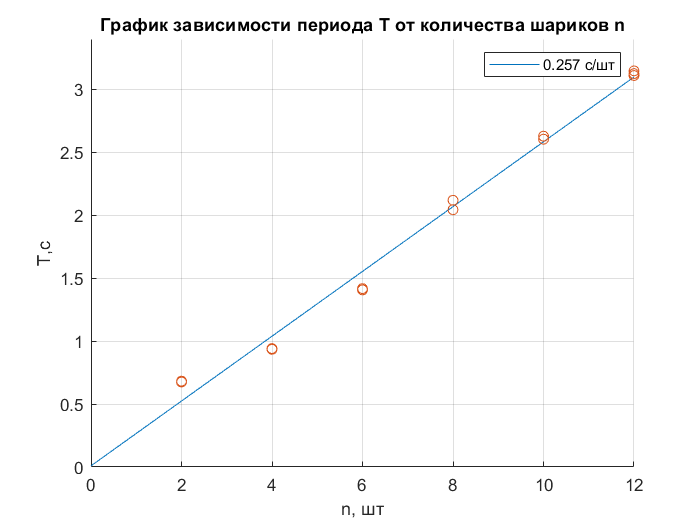

for k=0:1
    y1 = y1 + coeff_1(1-k+1) * xi.^k;
end
gr_1 = plot(xi, y1); 
scatter(x,y)
title("График зависимости периода T от количества шариков n")
xlabel("n, шт")
ylabel("T,c")
legend("0.257 c/шт")
hold off